# Probability of Detection with several SNR values for each Method : MF | ED | 2C

clear
load input_t.mat

By testing energy sepectrum with several SNR values, we end up with result that describes how the spectrum of energy is increasing by decreasing the SNR (Signal-to-Noise Ratio) and vice versa. 

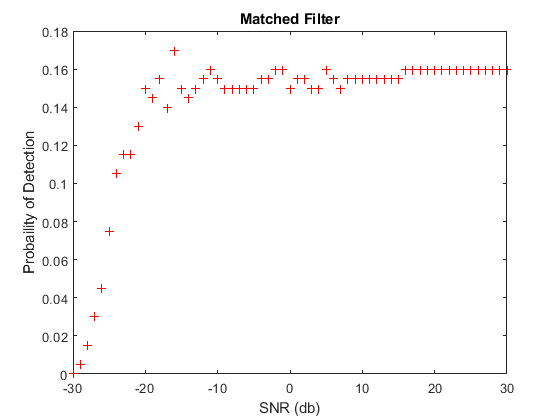

mySNR = -30:1:30;
snrValues(inputSignal,mySNR,100,'MF')

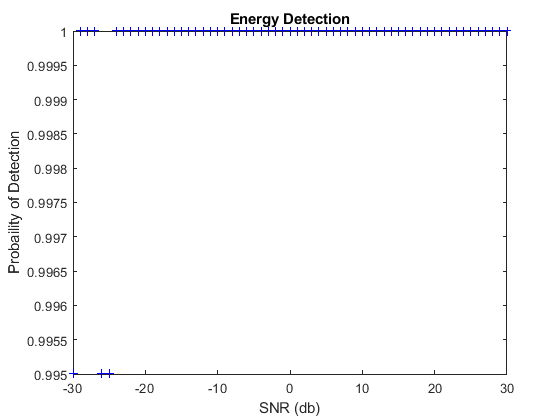

snrValues(inputSignal,mySNR,100,'ED')

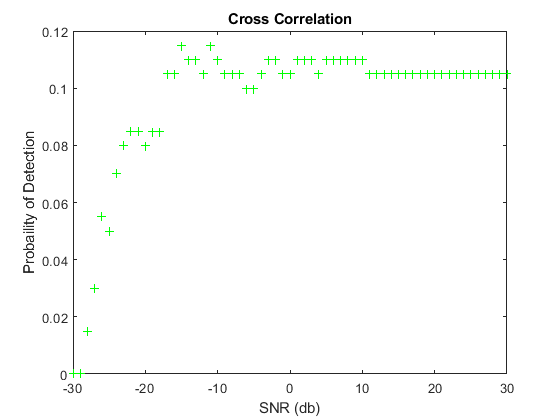

snrValues(inputSignal,mySNR,100,'2C')

load Pd_Pfa_MF.mat Pd_MF Pfa_MF
load Pd_Pfa_ED.mat Pd_ED Pfa_ED
load Pd_Pfa_2C.mat Pd_2C Pfa_2C

function snrValues(yourSignal,snr,threshold,Method) 
    if Method == "ED"
        for i = 1:length(snr)
            yourSignal = awgn(yourSignal,snr(i));
            find_PD_PFa_ED(yourSignal,threshold);        
            load Pd_Pfa_ED.mat Pd_ED      
            plot(snr(i),Pd_ED,'b+');
            hold on
            title('Energy Detection')
            xlabel('SNR (db)')
            ylabel('Probaility of Detection')
        end
        hold off
    elseif Method == "MF"
        for i = 1:length(snr)
            yourSignal = awgn(yourSignal,snr(i));
            find_PD_PFa_MF(yourSignal,threshold);        
            load Pd_Pfa_MF.mat Pd_MF      
            plot(snr(i),Pd_MF,'r+');
            hold on
            title('Matched Filter')
            xlabel('SNR (db)')
            ylabel('Probaility of Detection')
        end
        hold off
    elseif Method == "2C"
        for i = 1:length(snr)
            yourSignal = awgn(yourSignal,snr(i));
            find_PD_PFa_2C(yourSignal,threshold);        
            load Pd_Pfa_2C.mat Pd_2C      
            plot(snr(i),Pd_2C,'g+');
            hold on
            title('Cross Correlation')
            xlabel('SNR (db)')
            ylabel('Probaility of Detection')
        end
        hold off
    end        
end

#### I-  Create function to calculate Detection and False Alarm Probabilities for Energy Detection Method.

function find_PD_PFa_ED(yourSignal,threshold)
    Pd_buff(100)=0;
    Pfa_buff(100)=0;
    for j = 1:100
        highValue = 0;
        lowValue = 0;
        a = 0;
        for i = 1:length(yourSignal)
            a = a + abs(yourSignal(i)).^2;
            if a > threshold
                highValue = highValue + 1;
            else
                lowValue = lowValue + 1;
            end
        end
        Pd_buff(j) = highValue/length(yourSignal);
        Pfa_buff(j) = lowValue/length(yourSignal);
    end
    Pd_ED = sum(Pd_buff)/100;
    Pfa_ED = sum(Pfa_buff)/100;
    save Pd_Pfa_ED.mat a Pd_ED Pfa_ED
end

#### II- Create function to calculate Detection and False Alarm Probabilities for Matched Filter Method.

function find_PD_PFa_MF(yourSignal,threshold)
    Pd_buff(100)=0;
    Pfa_buff(100)=0;
    for j = 1:100
        highValue = 0;
        lowValue = 0;
        a = 0;
        for i = 1:length(yourSignal)
            a = abs(yourSignal(i));
            if a > threshold
                highValue = highValue + 1;
            else
                lowValue = lowValue + 1;
            end
        end
        Pd_buff(j) = highValue/length(yourSignal);
        Pfa_buff(j) = lowValue/length(yourSignal);
    end
    Pd_MF = sum(Pd_buff)/100;
    Pfa_MF = sum(Pfa_buff)/100;
    save Pd_Pfa_MF.mat a Pd_MF Pfa_MF
end

#### III- Create function to calculate Detection and False Alarm Probabilities for Cross Correlation Method.

function find_PD_PFa_2C(yourSignal,threshold)
    Pd_buff(100)=0;
    Pfa_buff(100)=0;
    for j = 1:100
        highValue = 0;
        lowValue = 0;
        a = 0;
        for i = 1:length(yourSignal)
            a = abs(yourSignal(i));
            if a > threshold
                highValue = highValue + 1;
            else
                lowValue = lowValue + 1;
            end
        end
        Pd_buff(j) = highValue/length(yourSignal);
        Pfa_buff(j) = lowValue/length(yourSignal);
    end
    Pd_2C = sum(Pd_buff)/100;
    Pfa_2C = sum(Pfa_buff)/100;
    save Pd_Pfa_2C.mat a Pd_2C Pfa_2C
end